# **PF**

## GLOBULOS BLANCOS

### a) Anotaciones

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\TF148_CS22'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.jpg'));

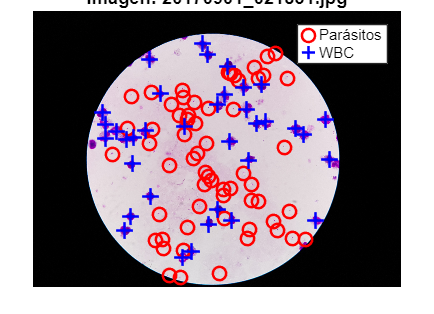

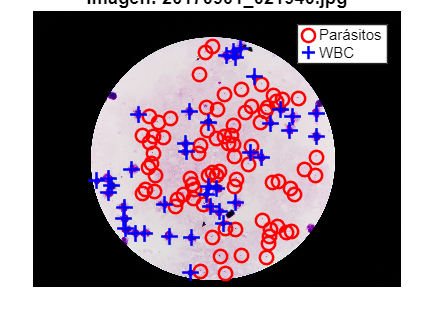

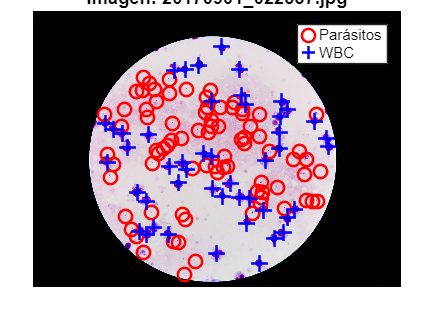

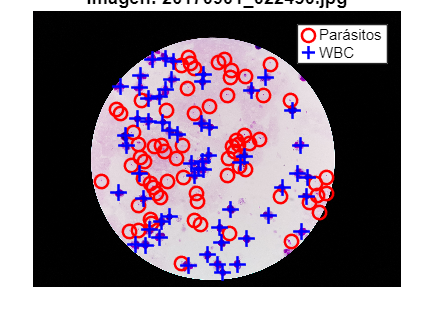

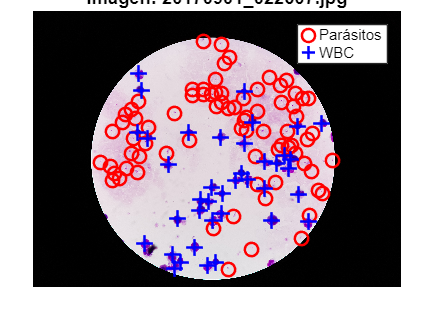

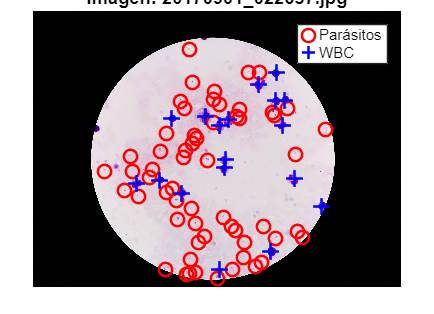

for i = 1:length(imageFiles)
    % Fitxategiaren izen osoa
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Irudia kargatu
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF148_CS22', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasite'), :);
    if ismember('Var8', datos.Properties.VariableNames) && ismember('Var9', datos.Properties.VariableNames)
    x_parasitos = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    y_parasitos = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    leyenda_parasitos = true;
    else
    disp(['No se encontraron coordenadas de parásitos en la imagen: ', imageFiles(i).name]);
    leyenda_parasitos = false;
    end
    
    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    if leyenda_parasitos
    legend('Parásitos', 'WBC');
    else
    legend('WBC');
    end
    hold off;
end

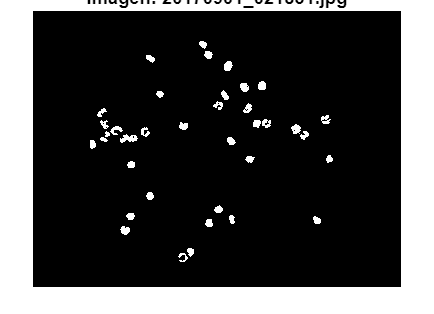

numero_de_wbc = 36

candidatos_a_wbc = 38

wbc_detectados = 35

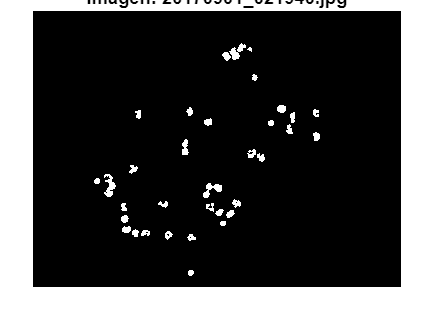

numero_de_wbc = 39

candidatos_a_wbc = 34

wbc_detectados = 31

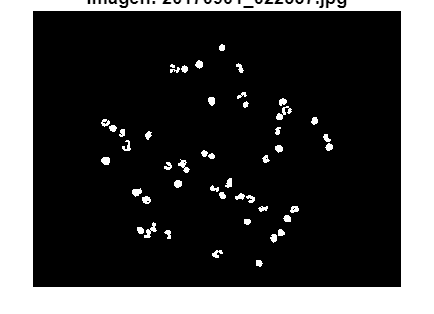

numero_de_wbc = 48

candidatos_a_wbc = 50

wbc_detectados = 48

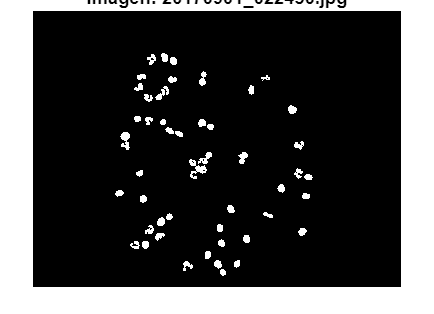

numero_de_wbc = 57

candidatos_a_wbc = 52

wbc_detectados = 52

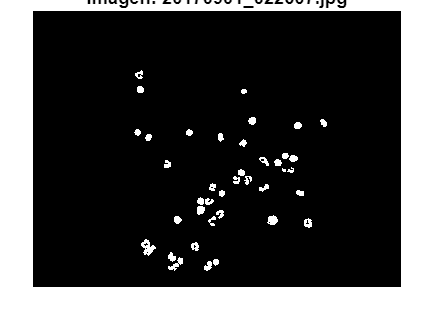

numero_de_wbc = 39

candidatos_a_wbc = 41

wbc_detectados = 38

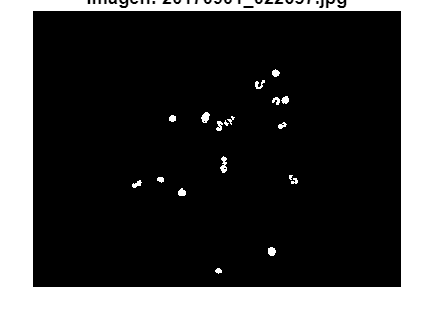

numero_de_wbc = 18

candidatos_a_wbc = 19

wbc_detectados = 17

total_wbc_reales = 0;
total_candidatos = 0;
total_wbc_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=im2double(rgb2gray(I));

    %====SEGMENTACIÓN===
    
    % 1. Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);

    % 2. Umbral
    threshold = graythresh(I_sinruido)*0.95;

    % 3. Binarizar
    M1 = imbinarize(I_sinruido, threshold);

    % 4. Rellenar agujeros
    M2 = imfill(M1, 'holes');

    % 5. Separar WBCs
    WBC_mask_ruido = M2 & ~M1;

    % 6. Eliminar pequeños ruidos
    WBC_mask = bwareaopen(WBC_mask_ruido, 1500);

    % Visualiza la máscara final
    figure;
    imshow(WBC_mask);hold on;
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF148_CS22', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;

    % ============Verificar el modelo========
    
    % Extraer el numero de wbc
    tamano=size(solo_WBC);
    numero_de_wbc = tamano(1,1)
    n=8;
    % Candidatos a wbc
    CC_2 = bwconncomp(WBC_mask,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_wbc=tamano(1,1)

    % wbc detectados
    umbral_distancia = 50;
    wbc_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada wbc real
    for p = 1:length(x_wbc)
        centro_real = [x_wbc(p), y_wbc(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                wbc_detectados = wbc_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un wbc detectado más de una vez
            end
        end
    end
    % Mostrar wbc detectados
    wbc_detectados

    % Sumas de los wbc reales, candidatos y detectados 
    total_wbc_reales = total_wbc_reales + numero_de_wbc;
    total_candidatos = total_candidatos + candidatos_a_wbc;
    total_wbc_detectados = total_wbc_detectados + wbc_detectados;
end


% Analizar modelo con estos resultados
total_wbc_reales

total_wbc_reales = 237

total_candidatos

total_candidatos = 234

total_wbc_detectados

total_wbc_detectados = 221


% Confusion matrix
TP=total_wbc_detectados;
FP=total_candidatos-total_wbc_detectados;
FN=total_wbc_reales-total_wbc_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 93.2489

precision=(TP/(TP+FP))*100

precision = 94.4444

## PARASITOS

### b) 2º Modelo Otsu

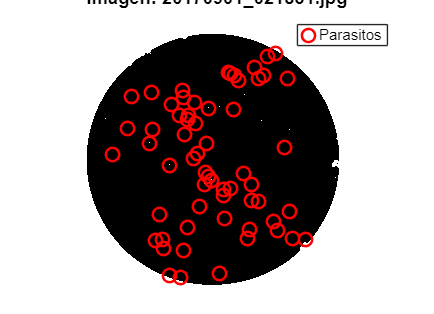

numero_de_parasitos = 61

candidatos_a_parasitos = 58

parasitos_detectados = 28

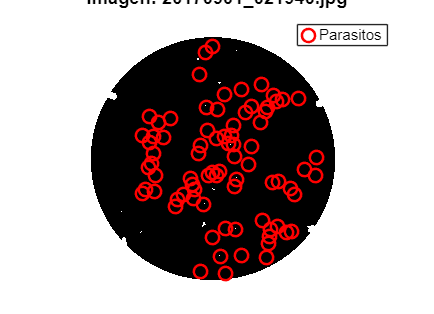

numero_de_parasitos = 79

candidatos_a_parasitos = 46

parasitos_detectados = 19

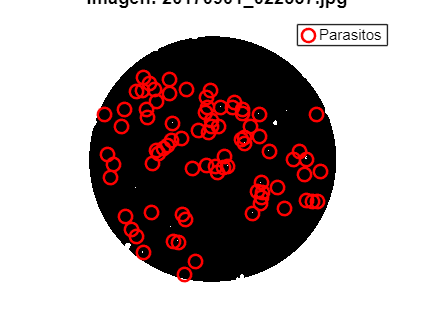

numero_de_parasitos = 81

candidatos_a_parasitos = 69

parasitos_detectados = 43

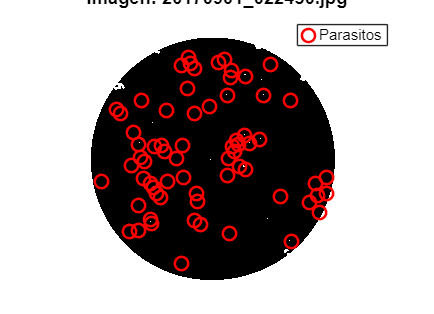

numero_de_parasitos = 68

candidatos_a_parasitos = 71

parasitos_detectados = 43

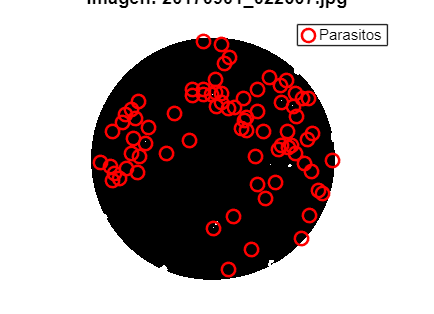

numero_de_parasitos = 77

candidatos_a_parasitos = 66

parasitos_detectados = 49

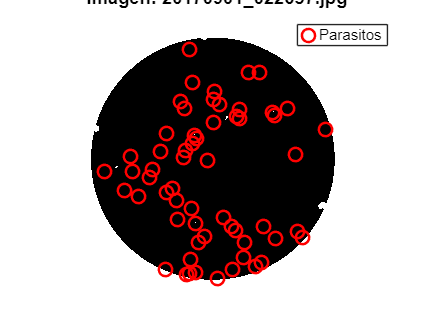

numero_de_parasitos = 59

candidatos_a_parasitos = 31

parasitos_detectados = 21

total_parasitos_reales = 0;
total_candidatos = 0;
total_parasitos_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=im2double(rgb2gray(I));

    %====SEGMENTACIÓN===
    
    % 1. Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);

    % 2. Umbral
    threshold = graythresh(I_sinruido)*0.95;

    % 3. Binarizar
    M1 = imbinarize(I_sinruido, threshold);

    % 4. Tener el negativo
    negativo= imcomplement(M1);

    % 5. Rellenar agujeros
    M2 = imfill(M1, 'holes');

    % 6. Separar WBCs
    WBC_mask_ruido = M2 & ~M1;

    % 7. Eliminar pequeños ruidos
    WBC_mask = bwareaopen(WBC_mask_ruido, 1500);

    % 8. Parasitos que se detecta cuando no debería de haber
    parasitos= negativo-WBC_mask;

    % Visualiza la máscara final
    figure;
    imshow(parasitos);hold on;
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF148_CS22', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasite'), :);
    if ismember('Var8', datos.Properties.VariableNames) && ismember('Var9', datos.Properties.VariableNames)
    x_parasitos = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    y_parasitos = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    leyenda_parasitos = true;
    else
    disp(['No se encontraron coordenadas de parásitos en la imagen: ', imageFiles(i).name]);
    leyenda_parasitos = false;
    end
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    if leyenda_parasitos
    legend('Parasitos');
    else
    legend('No parasitos');
    end
    hold off;

    % ============Verificar el modelo========
    
    % Extraer el numero de parasitos
    tamano=size(solo_parasitos);
    numero_de_parasitos = tamano(1,1)
    n=8;
    % Candidatos a parasitos
    CC_2 = bwconncomp(parasitos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_parasitos=tamano(1,1)

    % Parasitos detectados
    umbral_distancia = 50;
    parasitos_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada parásito real
    for p = 1:length(x_parasitos)
        centro_real = [x_parasitos(p), y_parasitos(p)];
        for d = 1:length(caracteristicas)
             if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                parasitos_detectados = parasitos_detectados + 1;
                detectados_usados(d) = true; 
                break;  % Evita contar un parásito detectado más de una vez
            end
        end
    end
    % Mostrar parasitos detectados
    parasitos_detectados

    % Sumas de los parasitos reales, candidatos y detectados 
    total_parasitos_reales = total_parasitos_reales + numero_de_parasitos;
    total_candidatos = total_candidatos + candidatos_a_parasitos;
    total_parasitos_detectados = total_parasitos_detectados + parasitos_detectados;
end


% Ananlizar modelo con estos resultados
total_parasitos_reales

total_parasitos_reales = 425

total_candidatos

total_candidatos = 341

total_parasitos_detectados

total_parasitos_detectados = 203


% Confusion matrix
TP=total_parasitos_detectados;
FP=total_candidatos-total_parasitos_detectados;
FN=total_parasitos_reales-total_parasitos_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 47.7647

precision=(TP/(TP+FP))*100

precision = 59.5308